# Q2. Creating Network - Image Classification *(50 points)*

## 0. Load data

Store the raw data in .csv file into `rawData` variable.

***Data description**

Each row of the array stores a label and a 28 x 28 gray image(which means one channel).

The first element of each row is the label of the image in the same row. Namely, the first column is labels of 5000 observations and the image of each observation is stored in column 2 - 785. 

rawData = readtable("Q2_dataset.csv");

## 1. Data Preprocessing & Spliting Dataset *(10 + 3 = 13 points)*

### 1.1. Data preprocessing (10)

Reshape `rawData` into `xData` and `yLabel`.

xData = rawData{:,(2:785)}

xData =      0     0     0     0     0     0     0     0     0     0     0    91    40    14    11     1    51    43     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     6    29    46    51   104   106   200   213   221   255   130    12    16     0     0
     0     0     0     0     0     0     1     0     0     0     4   168    72     9     7    15    45   153   119     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    33    34   103   213   250   228   221   237   255   239   178   207   120    19
     0     0     0     0     0     0     0     0    34   143   215   188   157   127    92   130   167   189   227   170    58     0     0     0     0     0     0     0     0     0     0     0     0     0    81   218   249   228   209   215   227   236   239   240   234   228   220   226   251   244
     0     0     0     0     0     0     0     0     0    23    64   124     4     0     

datapermute1 = permute(xData,[3 2 1]);
%size(datapermute1)
datareshape = reshape(datapermute1, [28 28 1 5000]);
%size(datareshape)
datapermute2 = permute(datareshape,[2 1 3 4]);
%size(datapermute2)
xData = datapermute2;
%size(xData)

yLabel=categorical(rawData{:,1})

yLabel = 5000×1 categorical 배열
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


categories(yLabel)

ans = 10×1 cell 배열
    {'0'}
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}
    {'8'}
    {'9'}


Display the 100th image of `xData`.

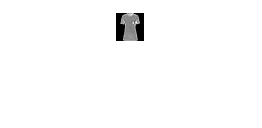

imshow(mat2gray(xData(:,:,:,100)))

### 1.2. Spliting dataset (3)

Split xData and yLabel into train and test sets. The ratio should be train : test = 8 : 2.

pt = cvpartition(yLabel,"Holdout",0.2)

'cvpartition'에는 Statistics and Machine Learning Toolbox이(가) 필요합니다.

trainidx = training(pt);
xTrain = xData(:,:,:,trainidx);
size(xTrain)
yTrain = yLabel(trainidx);
size(yTrain)
xTest = xData(:,:,:,~trainidx);
yTest = yLabel(~trainidx);

summary(yTrain)
summary(yTest)

If you don't complete '1. Data Preprocessing - Reshape', use the data below for the next questions.

load Q2_dataset_reshaped.mat

## 2. Creating Network *(5 points with no error)*

Create a Convolutional Neural Network.

layers = [imageInputLayer([28 28]); convolution2dLayer([3 3],20);...
    reluLayer(); maxPooling2dLayer([3 3]);...
    fullyConnectedLayer(10); softmaxLayer(); classificationLayer()]
analyzeNetwork(layers)

## 3. Training Network *(2 points with no error)*

Create appropriate training options and train the network

opts= trainingOptions("sgdm","MaxEpochs",50,"InitialLearnRate",0.0001,"Plots","training-progress")
newnet = trainNetwork(xTrain,yTrain,layers,opts)

## 4. Evaluating Network *(30)*

Calculate the prediction accuracy on the test data.

- Accuracy > 0.87             : 30 points

- 0.83 < Accuracy < 0.87  : 20 points

- Accuracy < 0.83             : 10 points

testPred = classify(newnet,xTest)
%summary(testPred)
testAcc = nnz(testPred==yTest)/numel(testPred)